clear all

Загрузка параметров

load curvefitting.mat

Описание данных с помощью функций (пытаемся использовать полиномы n-ой степени)

%   Строим модель, пытаемся описать все данные полиномом 5 степени poly5 
%   Все значения normalized by mean 1.061e+04 and std 2989


%   Разделить значения по расходам
%   значения начиная с 7500 (6 ая строка)

for i = 6:1:11

%   получение сил/моментов, соответствующих расходам
%   для каждой из сил строим и интерполируем(аппроксимируем) зависимость от частоты

%   Сохранение соответств. сил/моментов в 

Fr_cell{i-5}=Fr_comb{1,i};
Fx_cell{i-5}=Fx_comb{1,i};
Fy_cell{i-5}=Fy_comb{1,i};
Fz_cell{i-5}=Fz_comb{1,i};

Mr_cell{i-5}=Mr_comb{1,i};
Mx_cell{i-5}=Mx_comb{1,i};
My_cell{i-5}=My_comb{1,i};
Mz_cell{i-5}=Mz_comb{1,i};


end
%   объединяем, получаем ячейки, где строки - значения по x,y,z,r а столбцы - расходы 
% F_all=Fr_cell;
% F_all(end+1,:)=Fx_cell;
% F_all(end+1,:)=Fy_cell;
% F_all(end+1,:)=Fz_cell;

F_all=[Fx_cell; Fy_cell; Fz_cell; Fr_cell];

% M_all=Mr_cell;
% M_all(end+1,:)=Mx_cell;
% M_all(end+1,:)=My_cell;
% M_all(end+1,:)=Mz_cell;
M_all = [Mx_cell; My_cell; Mz_cell; Mr_cell];

FplusM = [F_all; M_all];
% save("FplusM.mat","FplusM", "RPM_comb")
% FM_all = {F_all; M_all}
% Fr_cell(1,i) - получение силы, соответствующей расходу

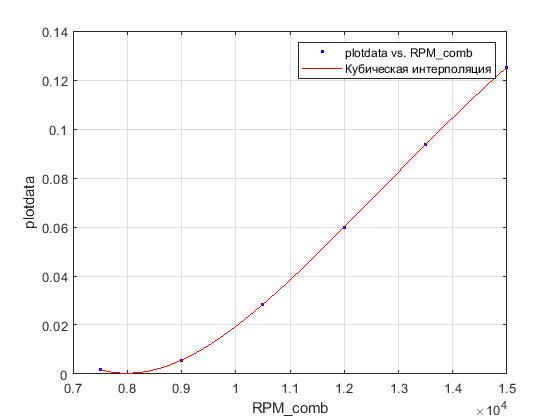

k = 2

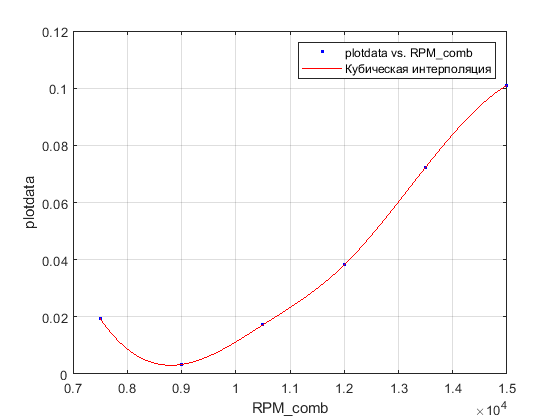

k = 3

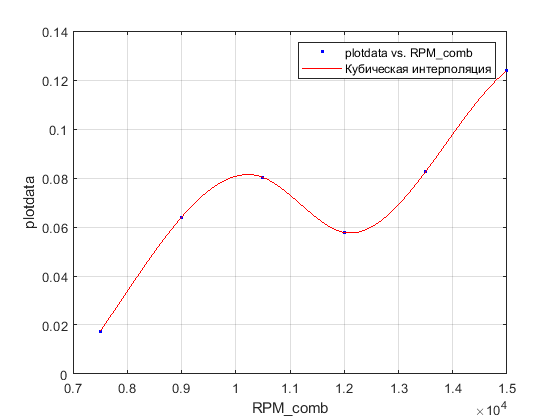

k = 4

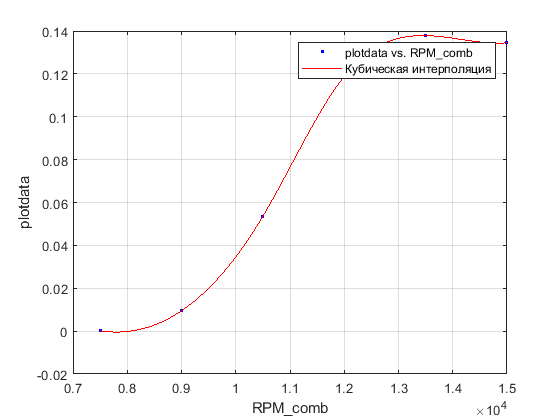

k = 5

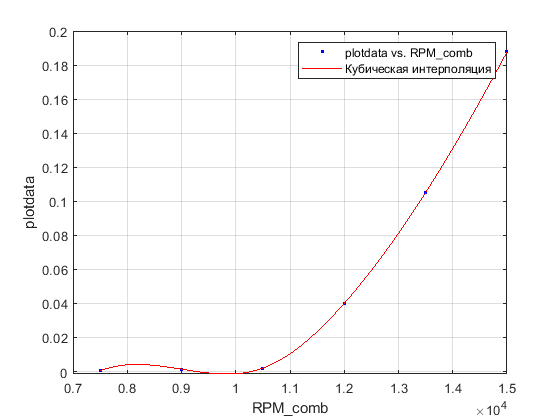

k = 6

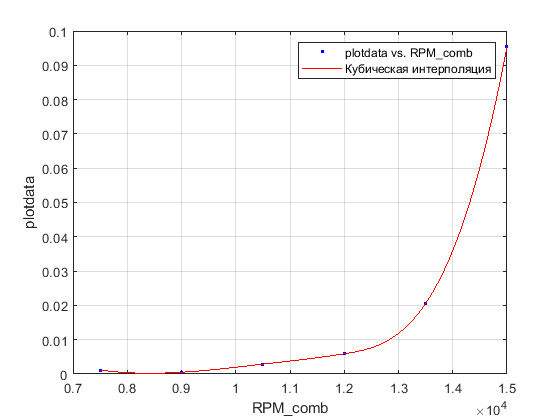

k = 7

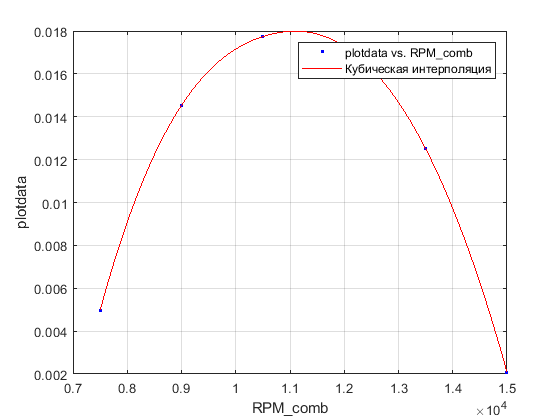

k = 8

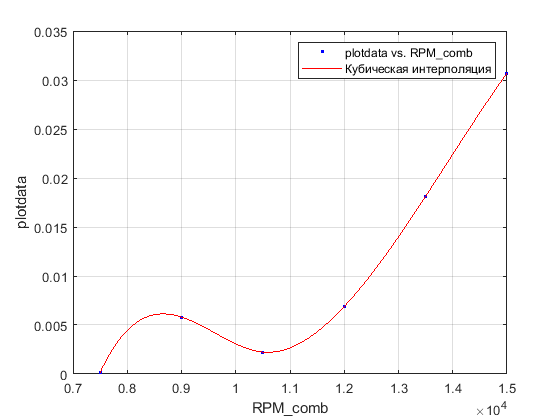

k = 9

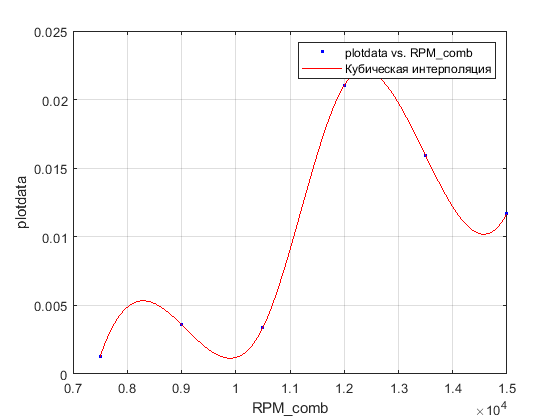

k = 10

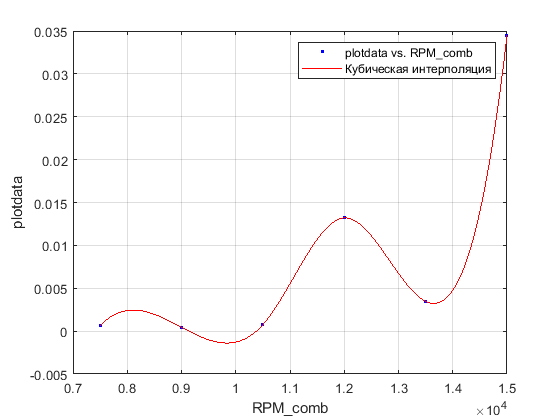

k = 11

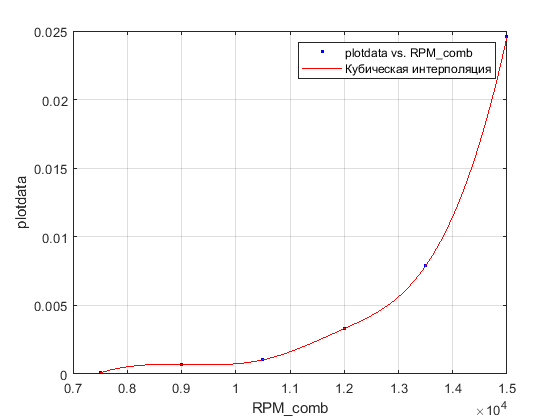

k = 12

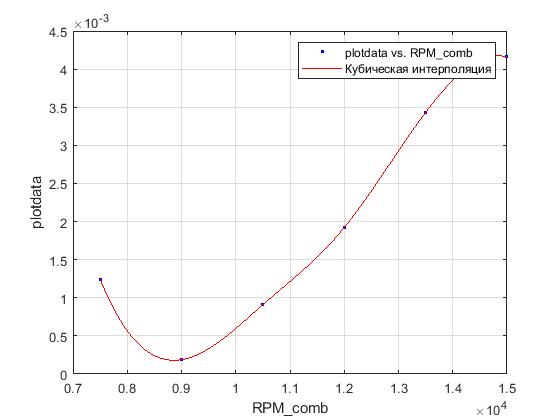

k = 13

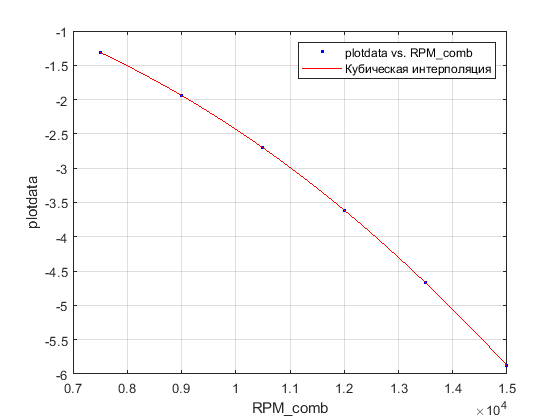

k = 14

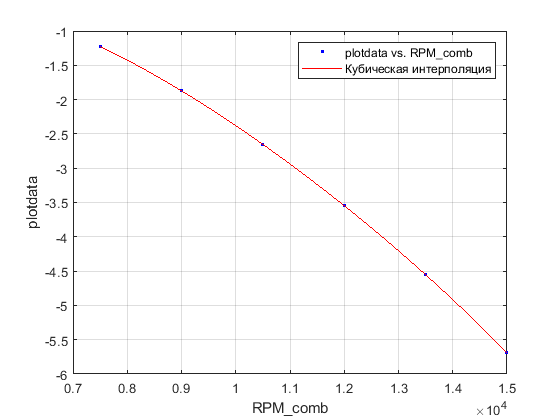

k = 15

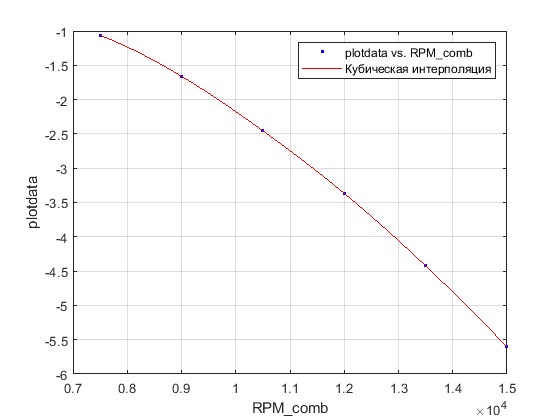

k = 16

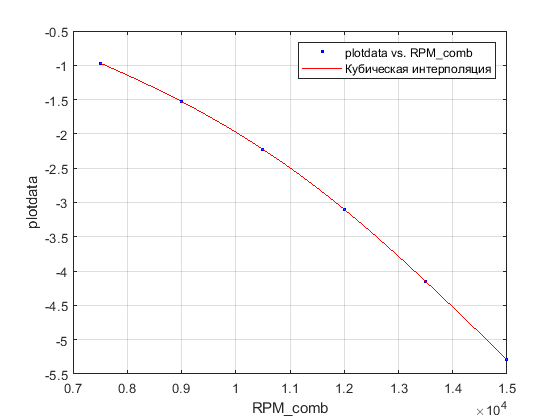

k = 17

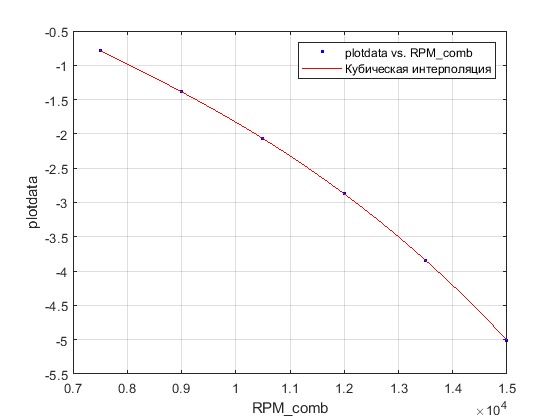

k = 18

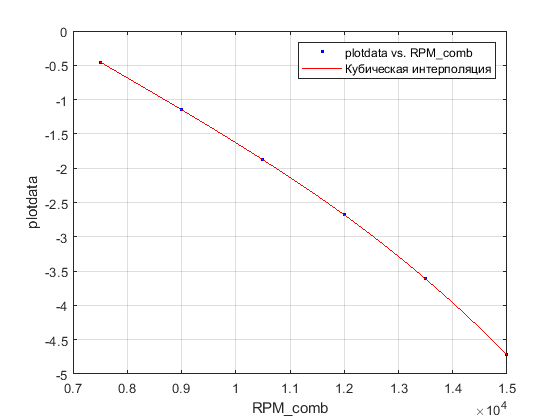

k = 19

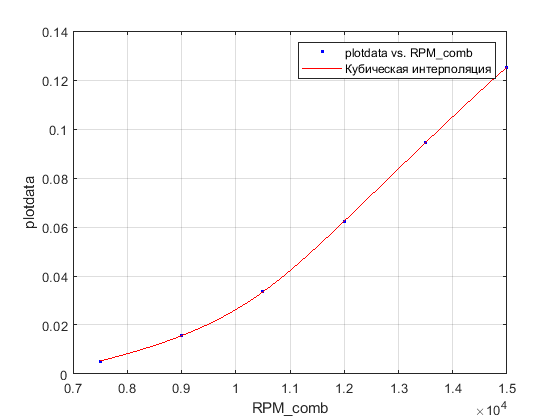

k = 20

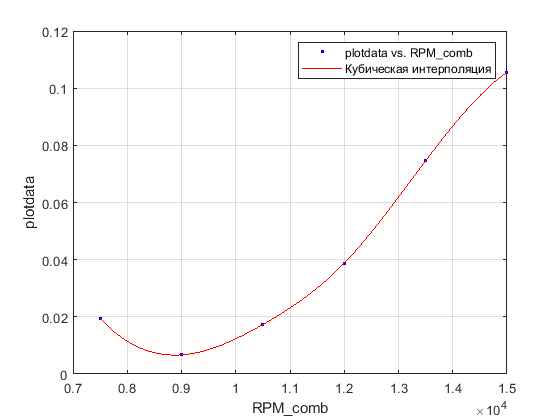

k = 21

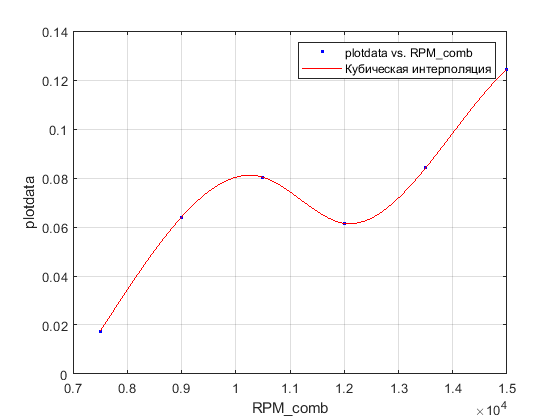

k = 22

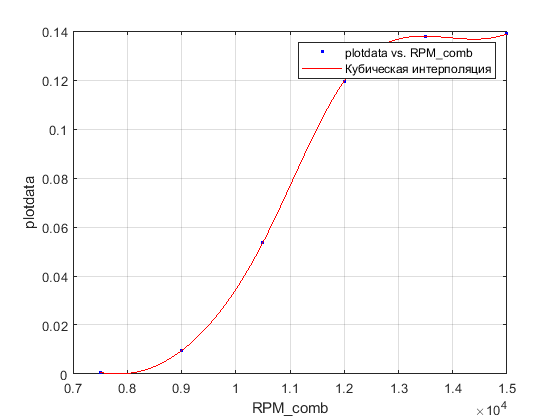

k = 23

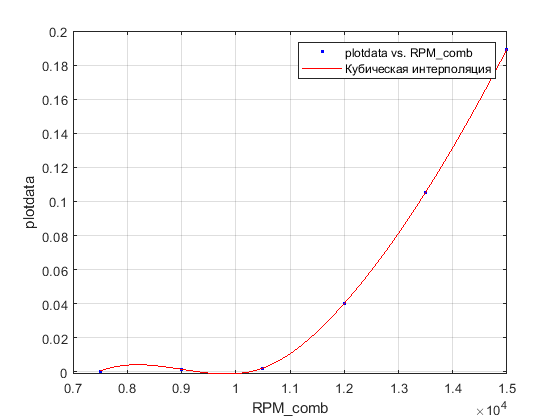

k = 24

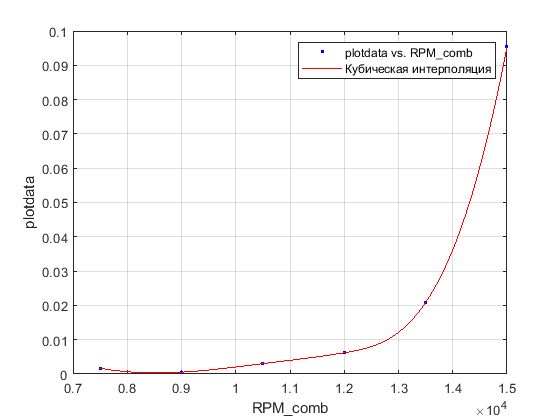

k = 25

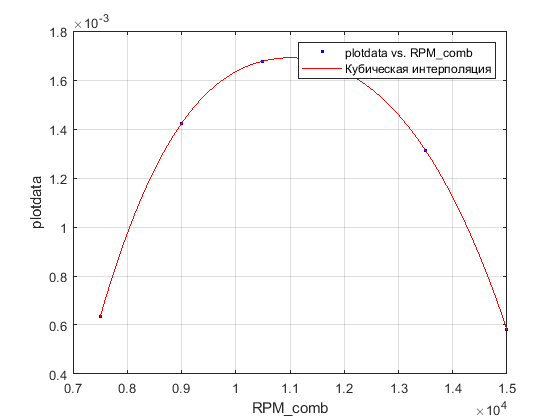

k = 26

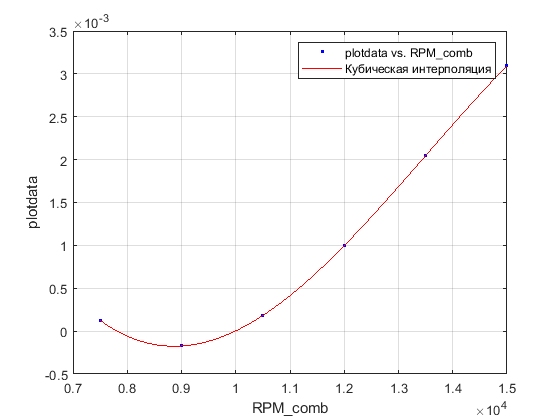

k = 27

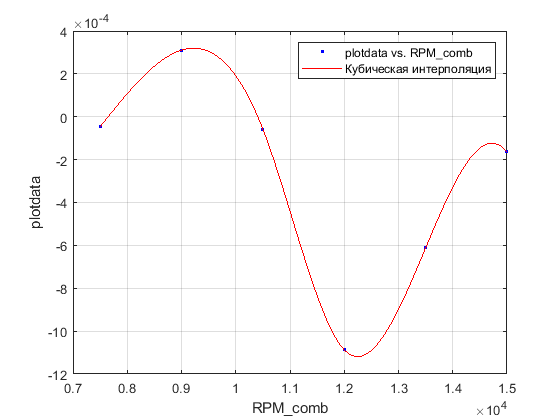

k = 28

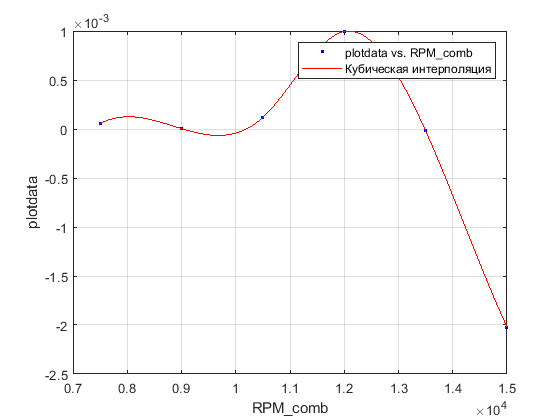

k = 29

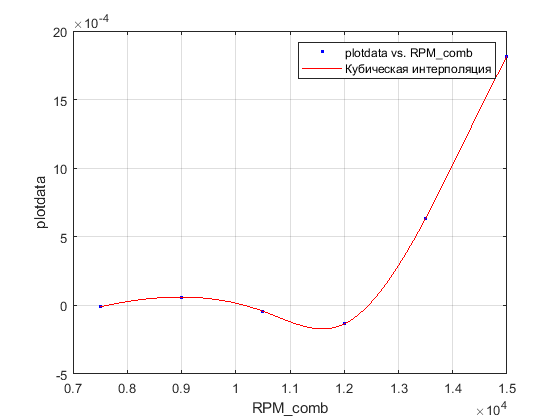

k = 30

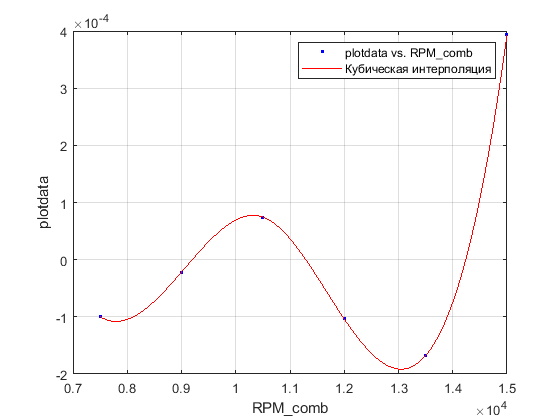

k = 31

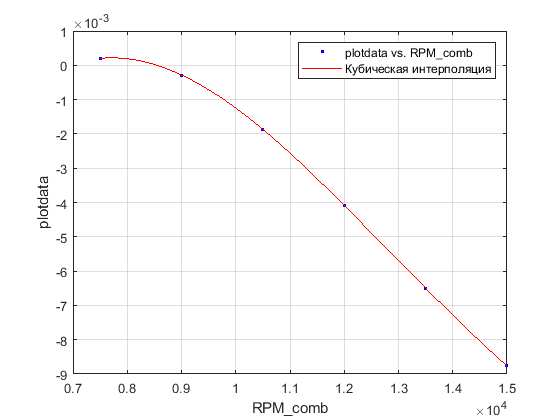

k = 32

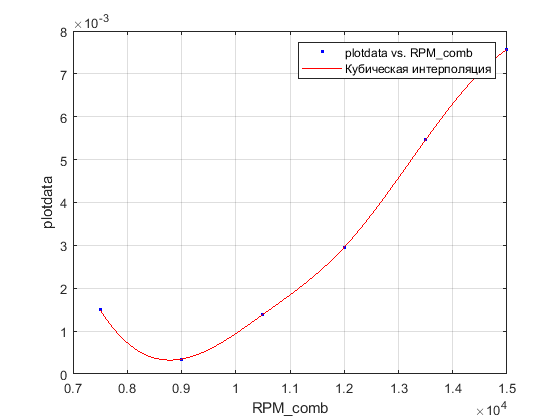

k = 33

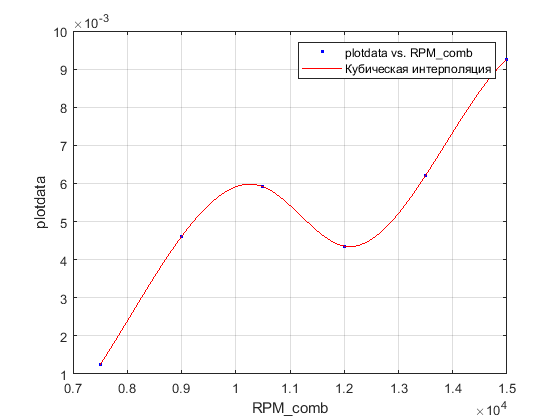

k = 34

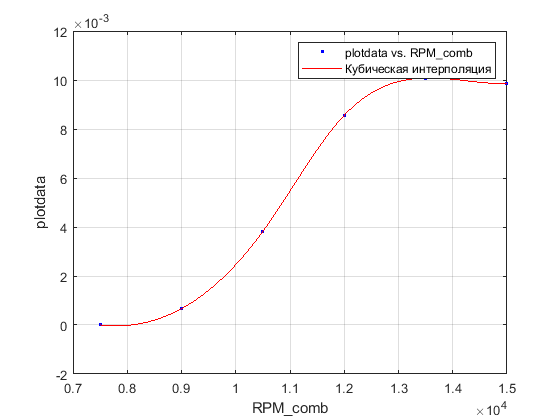

k = 35

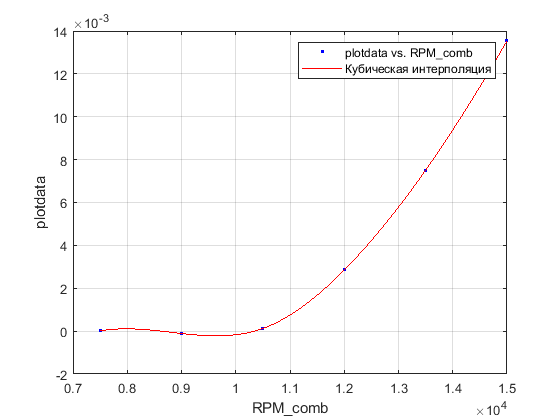

k = 36

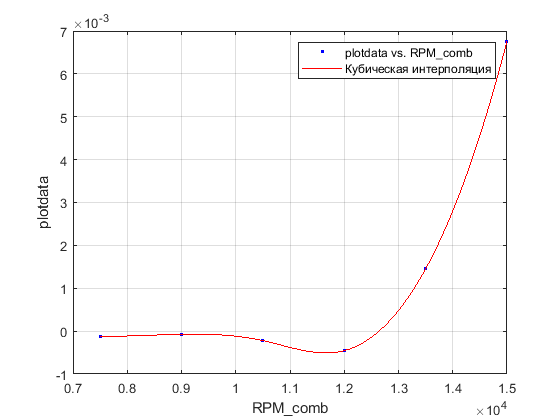

k = 37

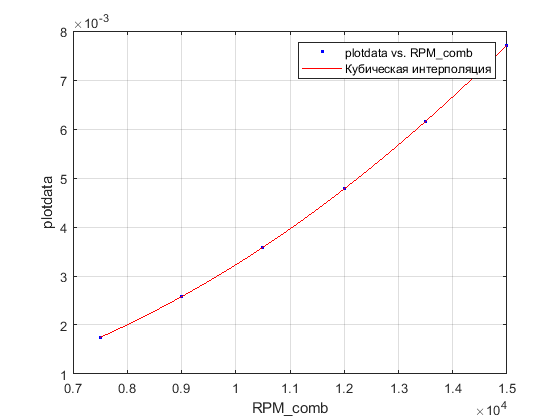

k = 38

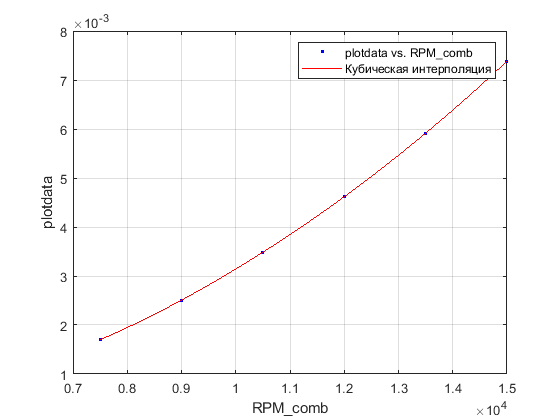

k = 39

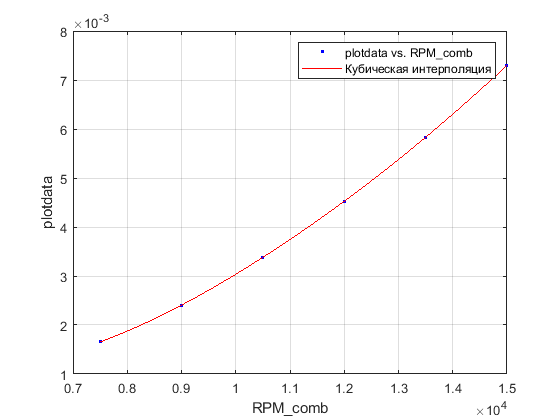

k = 40

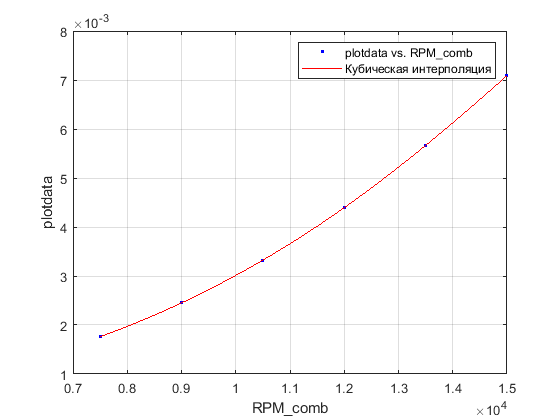

k = 41

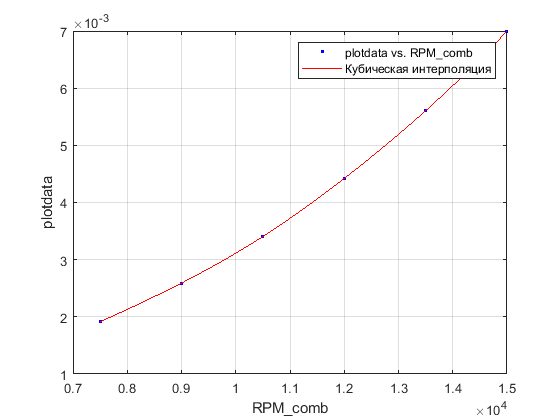

k = 42

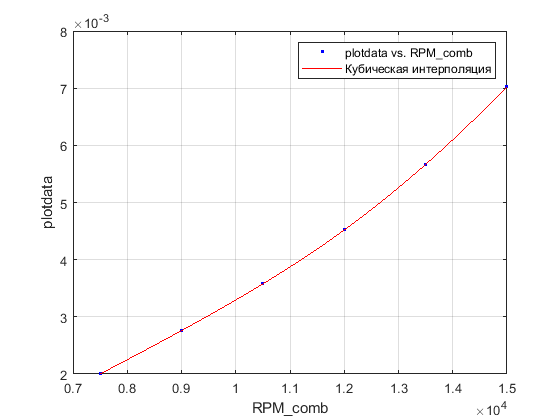

k = 43

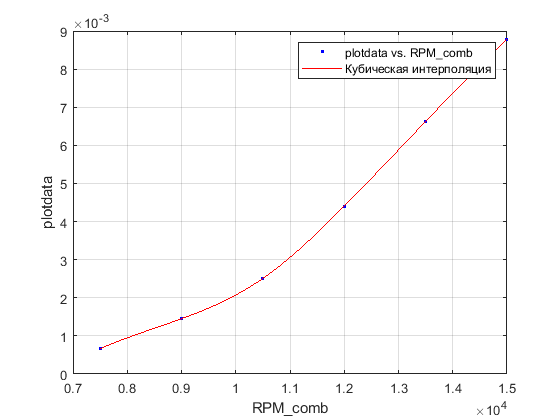

k = 44

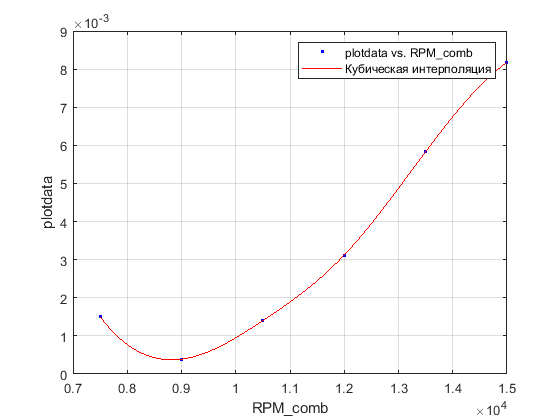

k = 45

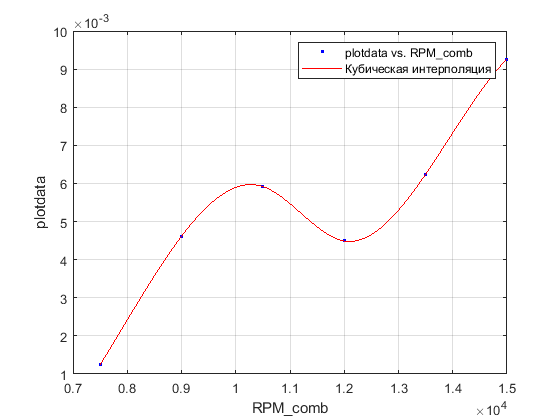

k = 46

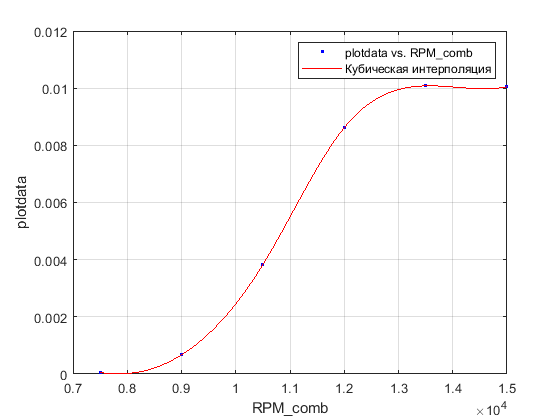

k = 47

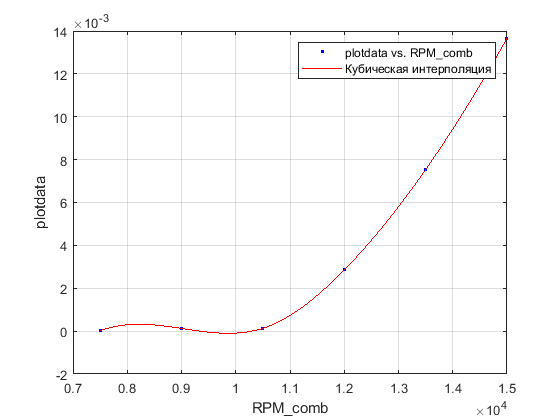

k = 48

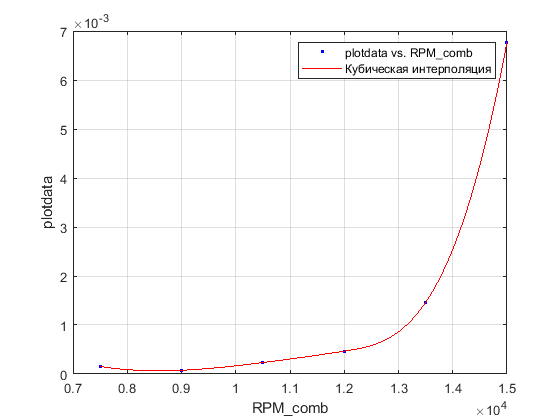

k = 49

% load FplusM.mat
k=1;             %номер графика, их счётчик количества
for i = 1:8      %по всем силам и моментам
    for j = 1:6 %по расходам (по столбцам)
i;
    j;
%      plotdata{k} = FplusM{i,j} %для всех строк (8)
    plotdata = FplusM{i,j};
    figure("Name","Силы/моменты от расхода")
%         subplot(2,3,j)
%     legstr=sprintf('Расход %.1f л/мин',k);
%     title('F'+legstr)
%         xlabel('Угл. скорость, об/мин')
%         ylabel('F [M], Н [Нм]')
%     legend(legstr,"Location","best")
%     plot(RPM_comb,cell2mat(Fr_cell(1,k)))
%     plots{k}=plot(RPM_comb,plotdata{k},'b--o')

% % Сравнение полинома и интерполяции, кубическая работает лучше!
% createFit_poly_vs_cubic(RPM_comb,plotdata);
    k
    createFit_cubic_interp(RPM_comb,plotdata);  

%   Сохранение графиков в переменную
% plots{k}=plot(RPM_comb,plotdata,'b--o');
    k=k+1;
    end
end


% for i = 1:numel(plots)/2
%     plot(RPM_comb,plots{1,i})
% end



% %   Для сил
% createFit_Fr(RPM,Fr)    %poly2  
% createFit_Fx(RPM,Fx)    %poly5
% createFit_Fy(RPM,Fy)
% createFit_Fz(RPM,Fz)

% %   Для моментов
% createFit_Mr(RPM,Mr)
% createFit_Mx(RPM,Mx)
% createFit_My(RPM,My)
% createFit_Mz(RPM,Mz)


% Fr_fittedmodel.p1
% Fr_fittedmodel.p2
% Fr_coeff=coeffvalues(Fr_fittedmodel)
% Fr_fittedmodel.feval